# Hybrid Dynamics Project

Jumper robot hybrid dynamics

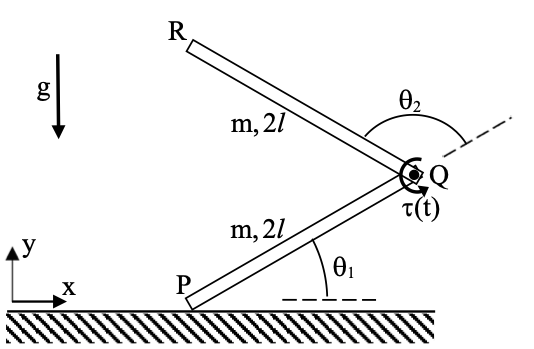

## Defining Variables

clear, close all
syms tau x y theta1 theta2 real
syms x_dot y_dot theta_dot_1 theta_dot_2 real
syms x_ddot y_ddot theta_ddot_1 theta_ddot_2 real
syms lambda_t lambda_n real
syms l m g I_c mu real positive
syms sigma real
assume(sigma == 1 | sigma == -1)
q = [x; y; theta1; theta2]

$$q = \left(\begin{array}{c} x\\ y\\ \theta_{1}\\ \theta_{2} \end{array}\right)$$

q_dot = [x_dot; y_dot; theta_dot_1; theta_dot_2]

$$q\_dot = \left(\begin{array}{c} \dot{x}\\ \dot{y}\\ {\dot{\theta }}_{1}\\ {\dot{\theta }}_{2} \end{array}\right)$$

q_ddot = [x_ddot; y_ddot; theta_ddot_1; theta_ddot_2]

$$q\_ddot = \left(\begin{array}{c} \ddot{x}\\ \ddot{y}\\ {\ddot{\theta }}_{1}\\ {\ddot{\theta }}_{2} \end{array}\right)$$

lambda = [lambda_t; lambda_n] % normal and tangential constraints forces

$$lambda = \left(\begin{array}{c} \lambda_{t}\\ \lambda_{n} \end{array}\right)$$

## Section 1 - Modeling System

% Center of Masses Position:
rC1 = [x + l*cos(theta1); y + l*sin(theta1); 0]

$$rC1 = \left(\begin{array}{c} x+l\,\cos\left(\theta_{1}\right)\\ y+l\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

rC2 = [x + 2*l*cos(theta1) + l*cos(theta1+theta2); y + 2*l*sin(theta1) + l*sin(theta1+theta2); 0]

$$rC2 = \left(\begin{array}{c} x+l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\\ y+l\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$


% Center of Mass Velocity:
vC1 = jacobian(rC1,q) * q_dot

$$vC1 = \left(\begin{array}{c} \dot{x}-l\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)\\ \dot{y}+l\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\\ 0 \end{array}\right)$$

vC2 = jacobian(rC2,q) * q_dot

$$vC2 = \left(\begin{array}{c} \dot{x}-{\dot{\theta }}_{1}\,\left(l\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l\,\sin\left(\theta_{1}\right)\right)-l\,{\dot{\theta }}_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ \dot{y}+{\dot{\theta }}_{1}\,\left(l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\right)+l\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\\ 0 \end{array}\right)$$


% Energy Calculations:
T1_tran = (1/2) * m * (vC1' * vC1) 

$$T1\_tran = \frac{m\,\left({\left(\dot{y}+l\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\right)}^{2}+{\left(\dot{x}-l\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)\right)}^{2}\right)}{2}$$

T2_tran = (1/2) * m * (vC2' * vC2)

$$T2\_tran = \frac{m\,\left({\left(\dot{y}+{\dot{\theta }}_{1}\,\left(l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\right)+l\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\right)}^{2}+{\left({\dot{\theta }}_{1}\,\left(l\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l\,\sin\left(\theta_{1}\right)\right)-\dot{x}+l\,{\dot{\theta }}_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\right)}^{2}\right)}{2}$$

T_tran = T1_tran + T2_tran

$$T\_tran = \frac{m\,\left({\left(\dot{y}+{\dot{\theta }}_{1}\,\left(l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\right)+l\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\right)}^{2}+{\left({\dot{\theta }}_{1}\,\left(l\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l\,\sin\left(\theta_{1}\right)\right)-\dot{x}+l\,{\dot{\theta }}_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\right)}^{2}\right)}{2}+\frac{m\,\left({\left(\dot{y}+l\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\right)}^{2}+{\left(\dot{x}-l\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)\right)}^{2}\right)}{2}$$

T1_rot = (1/2) * I_c * theta_dot_1^2 % I_c = m * l^2 / 3

$$T1\_rot = \frac{I_{c}\,{{\dot{\theta }}_{1}}^{2}}{2}$$

T2_rot = (1/2) * I_c * (theta_dot_1 + theta_dot_2)^2

$$T2\_rot = \frac{I_{c}\,{\left({\dot{\theta }}_{1}+{\dot{\theta }}_{2}\right)}^{2}}{2}$$

T_rot = T1_rot + T2_rot

$$T\_rot = \frac{I_{c}\,{\left({\dot{\theta }}_{1}+{\dot{\theta }}_{2}\right)}^{2}}{2}+\frac{I_{c}\,{{\dot{\theta }}_{1}}^{2}}{2}$$

T = T_rot + T_tran

$$T = \frac{I_{c}\,{\left({\dot{\theta }}_{1}+{\dot{\theta }}_{2}\right)}^{2}}{2}+\frac{I_{c}\,{{\dot{\theta }}_{1}}^{2}}{2}+\frac{m\,\left({\left(\dot{y}+{\dot{\theta }}_{1}\,\left(l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\right)+l\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\right)}^{2}+{\left({\dot{\theta }}_{1}\,\left(l\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l\,\sin\left(\theta_{1}\right)\right)-\dot{x}+l\,{\dot{\theta }}_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\right)}^{2}\right)}{2}+\frac{m\,\left({\left(\dot{y}+l\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\right)}^{2}+{\left(\dot{x}-l\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)\right)}^{2}\right)}{2}$$

V1 = m * g * rC1(2)

$$V1 = g\,m\,\left(y+l\,\sin\left(\theta_{1}\right)\right)$$

V2 = m * g * rC2(2)

$$V2 = g\,m\,\left(y+l\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l\,\sin\left(\theta_{1}\right)\right)$$

V = V1 + V2

$$V = g\,m\,\left(y+l\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,l\,\sin\left(\theta_{1}\right)\right)+g\,m\,\left(y+l\,\sin\left(\theta_{1}\right)\right)$$


% non conservative forces power:
Pnc = tau * theta_dot_2

$$Pnc = \tau \,{\dot{\theta }}_{2}$$


% Contact point velocity:
% vP = [x_dot;y_dot;0]
% therefore
W_t = sym([1 0 0 0])

$$W\_t = \left(\begin{array}{cccc} 1 & 0 & 0 & 0 \end{array}\right)$$

W_n = sym([0 1 0 0])

$$W\_n = \left(\begin{array}{cccc} 0 & 1 & 0 & 0 \end{array}\right)$$

W = [W_t;W_n]

$$W = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$


% Equations of Motion:
G = gradient(V,q)

$$G = \left(\begin{array}{c} 0\\ 2\,g\,m\\ g\,m\,\left(l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\right)+g\,l\,m\,\cos\left(\theta_{1}\right)\\ g\,l\,m\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}\right)$$

M = simplify(expand(hessian(T,q_dot)))

$$M = \left(\begin{array}{cccc} 2\,m & 0 & -l\,m\,\left(\sin\left(\theta_{1}+\theta_{2}\right)+3\,\sin\left(\theta_{1}\right)\right) & -l\,m\,\sin\left(\theta_{1}+\theta_{2}\right)\\ 0 & 2\,m & l\,m\,\left(\cos\left(\theta_{1}+\theta_{2}\right)+3\,\cos\left(\theta_{1}\right)\right) & l\,m\,\cos\left(\theta_{1}+\theta_{2}\right)\\ -l\,m\,\left(\sin\left(\theta_{1}+\theta_{2}\right)+3\,\sin\left(\theta_{1}\right)\right) & l\,m\,\left(\cos\left(\theta_{1}+\theta_{2}\right)+3\,\cos\left(\theta_{1}\right)\right) & 2\,I_{c}+6\,l^{2}\,m+4\,l^{2}\,m\,\cos\left(\theta_{2}\right) & I_{c}+l^{2}\,m+2\,l^{2}\,m\,\cos\left(\theta_{2}\right)\\ -l\,m\,\sin\left(\theta_{1}+\theta_{2}\right) & l\,m\,\cos\left(\theta_{1}+\theta_{2}\right) & I_{c}+l^{2}\,m+2\,l^{2}\,m\,\cos\left(\theta_{2}\right) & m\,l^{2}+I_{c} \end{array}\right)$$

dT_dq_dot = simplify(gradient(T,q_dot));
B = simplify((jacobian(dT_dq_dot,q)*q_dot-gradient(T,q)))

$$B = \left(\begin{array}{c} -l\,m\,\left(3\,{{\dot{\theta }}_{1}}^{2}\,\cos\left(\theta_{1}\right)+{{\dot{\theta }}_{1}}^{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+{{\dot{\theta }}_{2}}^{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\right)\\ -l\,m\,\left(3\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)+{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+{{\dot{\theta }}_{2}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\right)\\ -2\,l^{2}\,m\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right)\,\left(2\,{\dot{\theta }}_{1}+{\dot{\theta }}_{2}\right)\\ 2\,l^{2}\,m\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{2}\right) \end{array}\right)$$

Fq = gradient(Pnc,q_dot)

$$Fq = \left(\begin{array}{c} 0\\ 0\\ 0\\ \tau \end{array}\right)$$


% case 1 - no sllipage: |lambda_t| < mu * lambda_n ; lambda_n > 0 , v_t=0
Eqns1 = M*q_ddot + B + G == Fq + W'*lambda

% case 2 - sllipage: lambda_t = -sigma * mu * lambda_n; sigma = sign(v_t), lambda_n > 0
Eqns2 = subs(Eqns1,lambda_t,-sigma*mu*lambda_n)

% case 3 - free falling(no constraints): lambda_t = lambda_n = 0
Eqns3 = M*q_ddot + B + G == Fq

## Section 2 - Solution for each state

% parameters:
m=0.3 ; g=10 ; l=0.15 ; mu=0.3 ; tau_max=10 ; I_c=m*l^2/3;
% stick state:
global sol_stick_Func

% calculate W_dot (should be zero)
W_t_dot = (jacobian(W_t,q)*q_dot).';
W_n_dot = (jacobian(W_n,q)*q_dot).';
W_dot = [W_t_dot;W_n_dot]

$$W\_dot = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$


M_stick_tag = [M -W.'; W zeros(2)]

$$M\_stick\_tag = \left(\begin{array}{cccccc} 2\,m & 0 & -l\,m\,\left(\sin\left(\theta_{1}+\theta_{2}\right)+3\,\sin\left(\theta_{1}\right)\right) & -l\,m\,\sin\left(\theta_{1}+\theta_{2}\right) & -1 & 0\\ 0 & 2\,m & l\,m\,\left(\cos\left(\theta_{1}+\theta_{2}\right)+3\,\cos\left(\theta_{1}\right)\right) & l\,m\,\cos\left(\theta_{1}+\theta_{2}\right) & 0 & -1\\ -l\,m\,\left(\sin\left(\theta_{1}+\theta_{2}\right)+3\,\sin\left(\theta_{1}\right)\right) & l\,m\,\left(\cos\left(\theta_{1}+\theta_{2}\right)+3\,\cos\left(\theta_{1}\right)\right) & 2\,I_{c}+6\,l^{2}\,m+4\,l^{2}\,m\,\cos\left(\theta_{2}\right) & I_{c}+l^{2}\,m+2\,l^{2}\,m\,\cos\left(\theta_{2}\right) & 0 & 0\\ -l\,m\,\sin\left(\theta_{1}+\theta_{2}\right) & l\,m\,\cos\left(\theta_{1}+\theta_{2}\right) & I_{c}+l^{2}\,m+2\,l^{2}\,m\,\cos\left(\theta_{2}\right) & m\,l^{2}+I_{c} & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 \end{array}\right)$$

RHS_stick_tag = [Fq - B - G ; -W_dot * q_dot]

$$RHS\_stick\_tag = \left(\begin{array}{c} l\,m\,\left(3\,{{\dot{\theta }}_{1}}^{2}\,\cos\left(\theta_{1}\right)+{{\dot{\theta }}_{1}}^{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+{{\dot{\theta }}_{2}}^{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\right)\\ l\,m\,\left(3\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)+{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+{{\dot{\theta }}_{2}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\right)-2\,g\,m\\ 2\,l^{2}\,m\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right)\,\left(2\,{\dot{\theta }}_{1}+{\dot{\theta }}_{2}\right)-g\,l\,m\,\cos\left(\theta_{1}\right)-g\,m\,\left(l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\right)\\ -2\,m\,\sin\left(\theta_{2}\right)\,l^{2}\,{{\dot{\theta }}_{1}}^{2}-g\,m\,\cos\left(\theta_{1}+\theta_{2}\right)\,l+\tau \\ 0\\ 0 \end{array}\right)$$

sol_stick_Func = matlabFunction(subs((M_stick_tag \ RHS_stick_tag)));

% % slip state:
global sol_slip_Func
% define W_tag:
W_tag = W_n - sigma*mu*W_t

$$W\_tag = \left(\begin{array}{cccc} -\frac{3\,\sigma }{10} & 1 & 0 & 0 \end{array}\right)$$

W_tag_dot = (jacobian(W_tag,q)*q_dot).' % should be zero

$$W\_tag\_dot = \left(\begin{array}{cccc} 0 & 0 & 0 & 0 \end{array}\right)$$

% q_ddot_slip_tag = [q_ddot;lambda_n]
M_slip_tag = [M -W_tag.'; W_tag zeros(1)]

$$M\_slip\_tag = \left(\begin{array}{ccccc} 2\,m & 0 & -l\,m\,\left(\sin\left(\theta_{1}+\theta_{2}\right)+3\,\sin\left(\theta_{1}\right)\right) & -l\,m\,\sin\left(\theta_{1}+\theta_{2}\right) & \frac{3\,\sigma }{10}\\ 0 & 2\,m & l\,m\,\left(\cos\left(\theta_{1}+\theta_{2}\right)+3\,\cos\left(\theta_{1}\right)\right) & l\,m\,\cos\left(\theta_{1}+\theta_{2}\right) & -1\\ -l\,m\,\left(\sin\left(\theta_{1}+\theta_{2}\right)+3\,\sin\left(\theta_{1}\right)\right) & l\,m\,\left(\cos\left(\theta_{1}+\theta_{2}\right)+3\,\cos\left(\theta_{1}\right)\right) & 2\,I_{c}+6\,l^{2}\,m+4\,l^{2}\,m\,\cos\left(\theta_{2}\right) & I_{c}+l^{2}\,m+2\,l^{2}\,m\,\cos\left(\theta_{2}\right) & 0\\ -l\,m\,\sin\left(\theta_{1}+\theta_{2}\right) & l\,m\,\cos\left(\theta_{1}+\theta_{2}\right) & I_{c}+l^{2}\,m+2\,l^{2}\,m\,\cos\left(\theta_{2}\right) & m\,l^{2}+I_{c} & 0\\ -\frac{3\,\sigma }{10} & 1 & 0 & 0 & 0 \end{array}\right)$$

RHS_slip_tag = [Fq - B - G; -W_tag_dot * q_dot]

$$RHS\_slip\_tag = \left(\begin{array}{c} l\,m\,\left(3\,{{\dot{\theta }}_{1}}^{2}\,\cos\left(\theta_{1}\right)+{{\dot{\theta }}_{1}}^{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+{{\dot{\theta }}_{2}}^{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\right)\\ l\,m\,\left(3\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)+{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+{{\dot{\theta }}_{2}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+2\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\right)-2\,g\,m\\ 2\,l^{2}\,m\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right)\,\left(2\,{\dot{\theta }}_{1}+{\dot{\theta }}_{2}\right)-g\,l\,m\,\cos\left(\theta_{1}\right)-g\,m\,\left(l\,\cos\left(\theta_{1}+\theta_{2}\right)+2\,l\,\cos\left(\theta_{1}\right)\right)\\ -2\,m\,\sin\left(\theta_{2}\right)\,l^{2}\,{{\dot{\theta }}_{1}}^{2}-g\,m\,\cos\left(\theta_{1}+\theta_{2}\right)\,l+\tau \\ 0 \end{array}\right)$$

sol_slip_Func = matlabFunction(subs(M_slip_tag \ RHS_slip_tag));

% free state:
global sol_free_Func
RHS_free = Fq - B - G;
sol_free_Func = matlabFunction(subs(M \ RHS_free));


## Section 3 - impact law


M_Func = matlabFunction(subs(M));


## Section 4 - main jump

global rQ rR

rQ = matlabFunction(subs([x+2*l*cos(theta1);y+2*l*sin(theta1);0]));
rR = matlabFunction(subs([x + 2*l*cos(theta1) + 2*l*cos(theta1+theta2); y + 2*l*sin(theta1) + 2*l*sin(theta1+theta2); 0]));

## simulation

% state space vector: 
%[x x_dot y y_dot theta1 theta1_dot theta2 theta2_dot]'
X0 =[1 0 1 0 pi/3 0 pi/4 0];
tspan = [0 1];
op_free=odeset('reltol',1e-13,'abstol',1e-13,'Events',@events_free);
[T,X]=ode45(@sys_free,tspan,X0,op_free);

## functions

function dXdt = sys_stick(t,X)
    global sol_stick_Func
    tau=calc_tau(t);
    sol_stick_Num=sol_stick_Func(tau,X(5),X(7),X(6),X(8));
    dXdt=zeros(8,1);
    dXdt(1)=X(2);
    dXdt(2)=sol_stick_Num(1);
    dXdt(3)=X(4);
    dXdt(4)=sol_stick_Num(2);
    dXdt(5)=X(6);
    dXdt(6)=sol_stick_Num(3);
    dXdt(7)=X(8);
    dXdt(8)=sol_stick_Num(4);
end
% stick events function:
function [value,isterminal,direction]=events_stick(t,X)
    global sol_stick_Func
    mu=0.3;
    
    tau = calc_tau(t);
    sol_stick_Num=sol_stick_Func(tau,X(5),X(7),X(6),X(8));
    lambda_t = sol_stick_Num(5);
    lambda_n = sol_stick_Num(6);
    
  
    value = [lambda_t-mu*lambda_n;-lambda_t-mu*lambda_n];
    isterminal=[1;1];
    direction=[0;0];
end

% slip system function:
function dXdt = sys_slip(t,X)
    global sol_slip_Func sigma
    tau=calc_tau(t);
    
    sol_slip_Num=sol_slip_Func(sigma,tau,X(5),X(7),X(6),X(8));
    dXdt=zeros(8,1);
    dXdt(1)=X(2);
    dXdt(2)=sol_slip_Num(1);
    dXdt(3)=X(4);
    dXdt(4)=sol_slip_Num(2);
    dXdt(5)=X(6);
    dXdt(6)=sol_slip_Num(3);
    dXdt(7)=X(8);
    dXdt(8)=sol_slip_Num(4);
    
    % calculate sgn_slip - sigma - maybe need earlier
    W_t = [1 0 0 0];
    q_dot = [X(2);X(4);X(6);X(8)];
    v_t = W_t * q_dot;
    sigma = sign(v_t);
end

% events slip function:
function [value,isterminal,direction]=events_slip(t,X)
    global sol_slip_Func sigma
    
    W_t = [1 0 0 0];
    q_dot = [X(2);X(4);X(6);X(8)];
    vt = W_t*q_dot;
    sigma = sign(vt);
    
    tau = calc_tau(t);
    sol_slip_Num=sol_slip_Func(sigma,tau,X(5),X(7),X(6),X(8));
    
    lambda_n = sol_slip_Num(5);
    
    value = [lambda_n; vt];
    isterminal = [1;1];
    direction = [0;0];
end

% free state function:
function dXdt = sys_free(t,X)
    global sol_free_Func
    tau=calc_tau(t);
    sol_free_Num=sol_free_Func(tau,X(5),X(7),X(6),X(8));
    dXdt=zeros(8,1);
    dXdt(1)=X(2);
    dXdt(2)=sol_free_Num(1);
    dXdt(3)=X(4);
    dXdt(4)=sol_free_Num(2);
    dXdt(5)=X(6);
    dXdt(6)=sol_free_Num(3);
    dXdt(7)=X(8);
    dXdt(8)=sol_free_Num(4);
end

% free state events function:
function [value,isterminal,direction]=events_free(~,X)

    value = X(3);
    isterminal = 1;
    direction = 0;
end

% tau function:
function tau=calc_tau(t)
    
    tau=sin(t);
end